## Credits

Created: Martha N. Acosta, 25.01.2021

Supervised: Professor Francisco M. Gonzalez-Longatt

Github: [https://github.com/fglongatt/PowerSystemOperation](https://github.com/fglongatt/PowerSystemOperation)

### References:

     [1] Ebrahim Vaaheli, Practical Power System Operation. Hoboken, New Jersey: John Wiley & Sons, Inc., 2014.

     [2] Hadi Saadat, Power System Analysis. New York:  McGraw-Hill Companies, 1999. 

# Scenario and Contingency Analysis

The load flow formulation  requires considering four variables at each bus: net active power injection ($P_i$), net reactive power injection ($Q_i$), voltage magnitude ($V_i$) and voltage angle ($\theta_i$). The active and reactive power injections are calculated as follows : 


$$\begin{array}{l}
P_i =P_{\textrm{Gi}} -P_{\textrm{Di}} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)\\
Q_i =Q_{\textrm{Gi}} -Q_{\textrm{Di}} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)
\end{array}$$


where $P_{\textrm{Gi}}$ and $Q_{\textrm{Gi}}$ are active and reactive power generations at bus $i$, respectively.  $P_{\textrm{Di}}$ and $Q_{\textrm{Di}}$ are active and reactive power demand at bus $i$, respectively. 

The Kirchhoff’s laws at bus $i$ is  written as following :


$$\begin{array}{l}
\mathbf{I}=\mathbf{YV}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\right)\\
I_i =\frac{P_i -{jQ}_i }{\left|V_i \right|}e^{j\theta i} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(5\right)
\end{array}$$


where **V** is the vector of bus voltages, **I** is the vector of injected currents at the buses  and **Y** is the bus admittance matrix of the system . Substituting equation (5) in equation (4), the active and reactive power injections at bus $i$ are: 


$$\begin{array}{l}
P_i =\left|V_i \right|\sum_{j=1}^n \left|V_j \right|\left\lbrack G_{ij} \mathrm{cos}\left(\theta_i -\theta_j \right)+B_{ij} \mathrm{sin}\left(\theta_i -\theta_j \right)\right\rbrack \;\;\;\;\;\;\;\;\;\left(6\right)\\
Q_i =\left|V_i \right|\sum_{j=1}^n \left|V_j \right|\left\lbrack G_{ij} \mathrm{sin}\left(\theta_i -\theta_j \right)-B_{ij} \mathrm{cos}\left(\theta_i -\theta_j \right)\right\rbrack \;\;\;\;\;\;\;\;\;\;\left(7\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;
\end{array}$$


where $G_{\textrm{ij}} =\textrm{real}\left(Y_{\textrm{ij}} \right)$is the conductance and $B_{\textrm{ij}} =\textrm{imag}\left(Y_{\textrm{ij}} \right)$is the susceptance. $\theta$ is the voltage angle. 

**DC power flow **

The DC power flow provide a estimation of lines power flow on AC power systems. The non-linear model of AC system is simplified to a linear form through the following assumptions:

- Line resistances (active power losses) are negligible, i.e., $R\ll X$. Therefore, to performe DC power flow only the susceptance matrix is used. 

- Voltage angle differences are assumed to be small,  i.e., $\mathrm{sin}\left(\theta \right)=\theta$ and $\cos \left(\theta \right)=1$. 

-  Magnitudes of bus voltages are set to 1.0 pu (flat voltage profile).

-  Tap settings are ignored.

Considering the assumptions described above, the active power injection of the bus $i$ can be written as follows: 

                                                           
$$P_i =-B_{ij} \theta_i \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(8\right)$$
                                                

In general, for a power system of *n* number of busbar, the equation (8) is expressed in matrix form as follows: 

                   
$$\left\lbrack \begin{array}{c}
P_1 \\
P_2 \\
\vdots \\
P_i \\
\vdots \\
P_n 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{cccccc}
B_{11}  & B_{12}  & \cdots  & B_{1i}  & \cdots  & B_{1n} \\
B_{21}  & B_{22}  & \cdots  & B_{2i}  & \cdots  & B_{2i} \\
\vdots  & \vdots  &  & \vdots  &  & \vdots \\
B_{i1 }  & B_{i2 }  & \cdots  & B_{ii}  & \cdots  & B_{in} \\
\vdots  & \vdots  &  & \vdots  &  & \vdots \\
B_{n1 }  & B_{n2 }  & \cdots  & B_{ni}  & \cdots  & B_{nn} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta_1 \\
\theta_2 \\
\\
\theta_i \\
\\
\theta_n 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(9\right)$$
   

## EXAMPLE 

Consider the four-bus power system shown in **Figure1**, it consists of four busbars with two generator and two loads connected  by five transmission lines. The impedance of the transmission lines are given in in per unit expressed on the same bases. It is assumed  all the buses have the same voltage magnitude $\left|V_1 \right|=\left|V_2 \right|=\left|V_3 \right|=\left|V_4 \right|=1\ldotp 0\;\textrm{pu}$, the bus 1 assumed the *slack* *bus*, as a consequence, $\theta_1 =0°$. $\theta_2$, $\theta_3$and $\theta_4$ are the unknown voltages angles. 

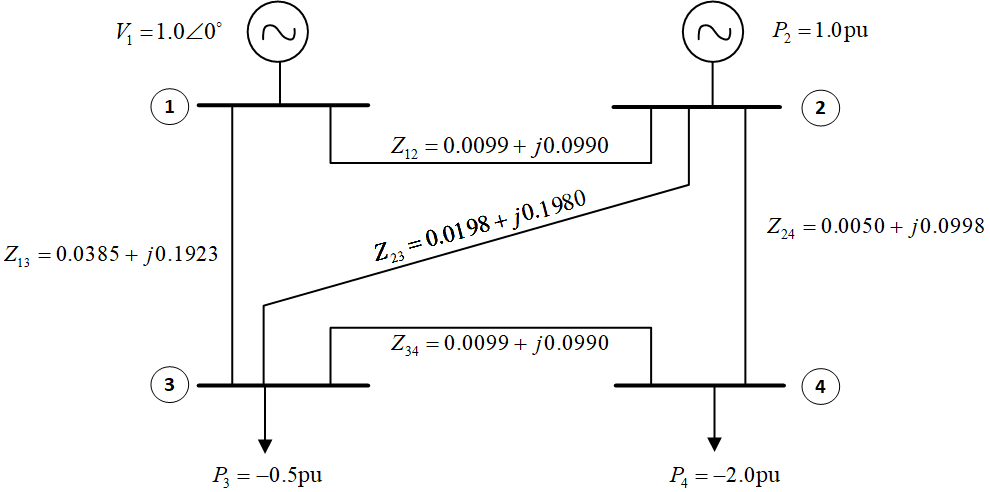                       

**Figure 1. Single-line diagram of the power system.    **     

***Procedure: ***

- Create a matrix containing the network connection and impedances of all transmission lines.

%         node i  node j     Z  =  R + jX
Zdata  = [   1       2     0.0099 + 0.099*i;
             1       3     0.0386 + 0.1924*i;
             2       3     0.0198 + 0.1980*i;
             2       4     0.0050 + 0.0998*i;
             3       4     0.0099 + 0.0990*i]; 
nbus = max(max(Zdata(:,1)), max(Zdata(:,2)));   %total number of buses
nbr = length(Zdata(:,1));    %total number of branches

         2. The bus 1 is assumed as slack bus,  therefore its voltage angle is defined as $\theta_1 =0°$. On the other hand, the  voltage angles of bus 2, 3 and 4 are unknow, $\theta =\left\lbrack \begin{array}{ccc}
\theta_1  & \theta_2  & \theta_3 \;\;\;\;\theta_4 
\end{array}\right\rbrack$ .  Be aware all angles will be expressed in radians. 

theta = [0; NaN; NaN; NaN]

theta =      0
   NaN
   NaN
   NaN


       3. The active power in per unit at bus 1, 2, 3 and 4 is$\;\mathbf{P}=\left\lbrack \begin{array}{ccc}
P_1  & P_2  & P_3 \;\;\;P_4 
\end{array}\right\rbrack$. Since bus 1  is assumed as slack bus, $P_1$ is unknow. 

P = [NaN; 1; -0.5; -2]

P =        NaN
    1.0000
   -0.5000
   -2.0000


        4.  Build the admittance matrix

Y = build_Y(Zdata)

Y =    2.0025 -14.9974i  -1.0001 +10.0010i  -1.0024 + 4.9964i   0.0000 + 0.0000i
  -1.0001 +10.0010i   2.0009 -24.9965i  -0.5001 + 5.0005i  -0.5007 + 9.9950i
  -1.0024 + 4.9964i  -0.5001 + 5.0005i   2.5025 -19.9979i  -1.0001 +10.0010i
   0.0000 + 0.0000i  -0.5007 + 9.9950i  -1.0001 +10.0010i   1.5008 -19.9960i


        5.  The suceptance matrix (**B**) is calculated  by taking the imaginary part of the admittance matrix ($\mathbf{Y}$):

B = imag(Y)

B =   -14.9974   10.0010    4.9964         0
   10.0010  -24.9965    5.0005    9.9950
    4.9964    5.0005  -19.9979   10.0010
         0    9.9950   10.0010  -19.9960


        6.  As bus 1 is considered as slack,  the first row of the active power injection vector is  disregarded. The first row and column of **B** are disregarded. 

P_reduced = P(2:nbus)

P_reduced =     1.0000
   -0.5000
   -2.0000


B_reduced = B(2:nbus,2:nbus)

B_reduced =   -24.9965    5.0005    9.9950
    5.0005  -19.9979   10.0010
    9.9950   10.0010  -19.9960


      7.  Calculate the voltage angles $\theta_2$, $\theta_3$ and $\theta_4$  using  equation (9) as following:                                                                                                                                          

theta (2:4) = double((-B_reduced)\P_reduced)

theta =          0
   -0.0750
   -0.1501
   -0.2126


Please, be aware those angles are defined in radians.

     8. Compute the total active power provided by the slack bus using the following equation: 

$P_1$= $B_{11}$$\theta_1$+$B_{12}$$\theta_2$+...+$B_{1i}$$\theta_i$+$B_{1n}$$\theta_n$

P1 = double(-B(1,:)*theta)

P1 = 1.5000

P (1,1) = P1

P =     1.5000
    1.0000
   -0.5000
   -2.0000


      9. Perform the contingency analysis by disconnecting one transmission line at a time and computing voltages angles, the active power provided by the slack bus and the active power flow through the transmission lines. 

nC = 5;
bus = 1:1:nbus;
for k = 1:nC
    Zdata_contingency = Zdata;
    Zdata_contingency (k,3) = 0;
    Y = build_Y(Zdata_contingency);     %Step 4
    B = imag(Y);                        %Step 5
    P_reduced = P(2:nbus);              %Step 6
    B_reduced = B(2:nbus,2:nbus);
    theta (2:4) = double((-B_reduced)\P_reduced); %Step 7
    P1 = double(-B(1,:)*theta);    %Step 8
    P (1,1) = P1;

Contingency 1 : Disconnecting transmission line 1-2


ans = 4×3 table
    Bus    Pi (pu)    Voltage angle (rad)
    ___    _______    ___________________

     1       1.5                  0      
     2         1           -0.30019      
     3      -0.5           -0.30022      
     4        -2           -0.40022      


ans = 5×3 table
    From bus i    To bus j     Pij (pu) 
    __________    ________    __________

        1            2                 0
        1            3            1.5604
        2            3        0.00015276
        2            4            1.0024
        3            4            1.0102


Contingency 2 : Disconnecting transmission line 1-3


ans = 4×3 table
    Bus    Pi (pu)    Voltage angle (rad)
    ___    _______    ___________________

     1       1.5                  0      
     2         1           -0.14999      
     3      -0.5           -0.30002      
     4        -2           -0.32505      


ans = 5×3 table
    From bus i    To bus j    Pij (pu)
    __________    ________    ________

        1            2          1.515 
        1            3              0 
        2            3        0.75777 
        2            4         1.7541 
        3            4        0.25277 


Contingency 3 : Disconnecting transmission line 2-3


ans = 4×3 table
    Bus    Pi (pu)    Voltage angle (rad)
    ___    _______    ___________________

     1       1.5                   0     
     2         1           -0.060004     
     3      -0.5            -0.18011     
     4        -2             -0.2201     


ans = 5×3 table
    From bus i    To bus j    Pij (pu)
    __________    ________    ________

        1            2         0.6061 
        1            3        0.93612 
        2            3              0 
        2            4         1.6041 
        3            4         0.4039 


Contingency 4 : Disconnecting transmission line 2-4


ans = 4×3 table
    Bus    Pi (pu)    Voltage angle (rad)
    ___    _______    ___________________

     1       1.5                   0     
     2         1           -0.020041     
     3      -0.5             -0.2601     
     4        -2            -0.46008     


ans = 5×3 table
    From bus i    To bus j    Pij (pu)
    __________    ________    ________

        1            2        0.20243 
        1            3         1.3519 
        2            3         1.2124 
        2            4              0 
        3            4           2.02 


Contingency 5 : Disconnecting transmission line 3-4


ans = 4×3 table
    Bus    Pi (pu)    Voltage angle (rad)
    ___    _______    ___________________

     1       1.5                  0      
     2         1           -0.10001      
     3      -0.5           -0.10004      
     4        -2           -0.30011      


ans = 5×3 table
    From bus i    To bus j     Pij (pu) 
    __________    ________    __________

        1            2            1.0102
        1            3           0.51995
        2            3        0.00016568
        2            4             2.005
        3            4                 0


              Calculating the power flow through the transmission lines using the following equation: 


$$P_{ij} =\frac{\theta_i -\theta_j }{X_{ij} }$$


    for br = 1:nbr
        if br == k
           Pij(br,1) = 0;
        else 
           Pij(br,1) = (theta(Zdata_contingency(br,1))-theta(Zdata_contingency(br,2)))/imag(Zdata_contingency(br,3));
        end
    end
    fprintf('Contingency %i : Disconnecting transmission line %i-%i\n', k,Zdata_contingency(k,1), Zdata_contingency(k,2)) 
    name = {'Bus','Pi (pu)','Voltage angle (rad)'};
    table(bus', P, theta, 'VariableNames',name)
    name1 = {'From bus i','To bus j','Pij (pu)'};
    table(Zdata_contingency (:,1), Zdata_contingency (:,2), Pij, 'VariableNames',name1)
end

### **Function to build Ybus **

The admittance matrix ($\mathbf{Y}$) must be created as following [2]:

                                           
$$\mathbf{Y}=\left\lbrack \begin{array}{cccccc}
Y_{11}  & Y_{12}  & \cdots  & Y_{1i}  & \cdots  & Y_{1n} \\
Y_{21}  & Y_{22}  & \cdots  & Y_{2i}  & \cdots  & Y_{2i} \\
\vdots  & \vdots  &  & \vdots  &  & \vdots \\
Y_{i1 }  & Y_{i2 }  & \cdots  & Y_{ii}  & \cdots  & Y_{in} \\
\vdots  & \vdots  &  & \vdots  &  & \vdots \\
Y_{n1 }  & Y_{n2 }  & \cdots  & Y_{ni}  & \cdots  & Y_{nn} 
\end{array}\right\rbrack \;\;\;\;\;\;\;i=1,2,\ldotp \ldotp \ldotp ,n\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$
                                              

where *n* represent the number of nodes in the nertwork. The diagonal element of each node is computed as the sum of admittances connected to it. It is known as the self-admitance:

                                                                   
$$Y_{\textrm{ii}} =\sum_{j=0}^n y_{\textrm{ij}} \;\;\;\;\;\;\;\;\;\;\;\;\;j\not= i\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$$
                                                                

The off-diagonal element is equal to the negative of the admitance between the nodes. It is know the mutual admittance or transfer admittance: 

                                              
$$Y_{ij} =Y_{ji} =-y_{ij} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\right)$$
                                                                          

Remember the admittance is computed as the inverse of the impedance: 

                                  
$$y_{ik} =\frac{1}{Z_{ij} }=\frac{1}{R_{ij} +jX_{ij} }=G_{ij} +jB_{ij\;\;} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\right)$$
                                                  

function Y = build_Y(Z_data)
from = Z_data(:,1); to = Z_data(:,2);
nbr=length(Z_data(:,1)); nbus = max(max(from), max(to));
Z = Z_data(:,3);                          % Branch Impedance 
y= ones(nbr,1)./Z;                      % Branch Admittance

Y=zeros(nbus,nbus);          
for k = 1:nbr;   % Off-diagonal elements 
    if from(k) > 0 && to(k) > 0
    Y(from(k),to(k)) = Y(from(k),to(k)) - y(k);
    Y(to(k),from(k)) = Y(from(k),to(k));
    end
end
for n = 1:nbus       % Diagonal elements
    for k = 1:nbr
        if from(k) == n || to(k) == n
            Y(n,n) = Y(n,n) + y(k);
        else
        end
    end
end
end 